# Create and Customize ezpolar Plots

`ezpolar` provides an easy-to-use polar coordinate plotter.

### Define Function

Define a simple sine function $r\;=\;\sin \left(\frac{5}{4}*t\right)$ .

f = @(t) sin (5/4 * t);

### Basic ezpolar Plot

Visualize the defined function in the default range $t=\left\lbrack 0\ldotp 2\pi \right\rbrack$ using `ezpolar`.

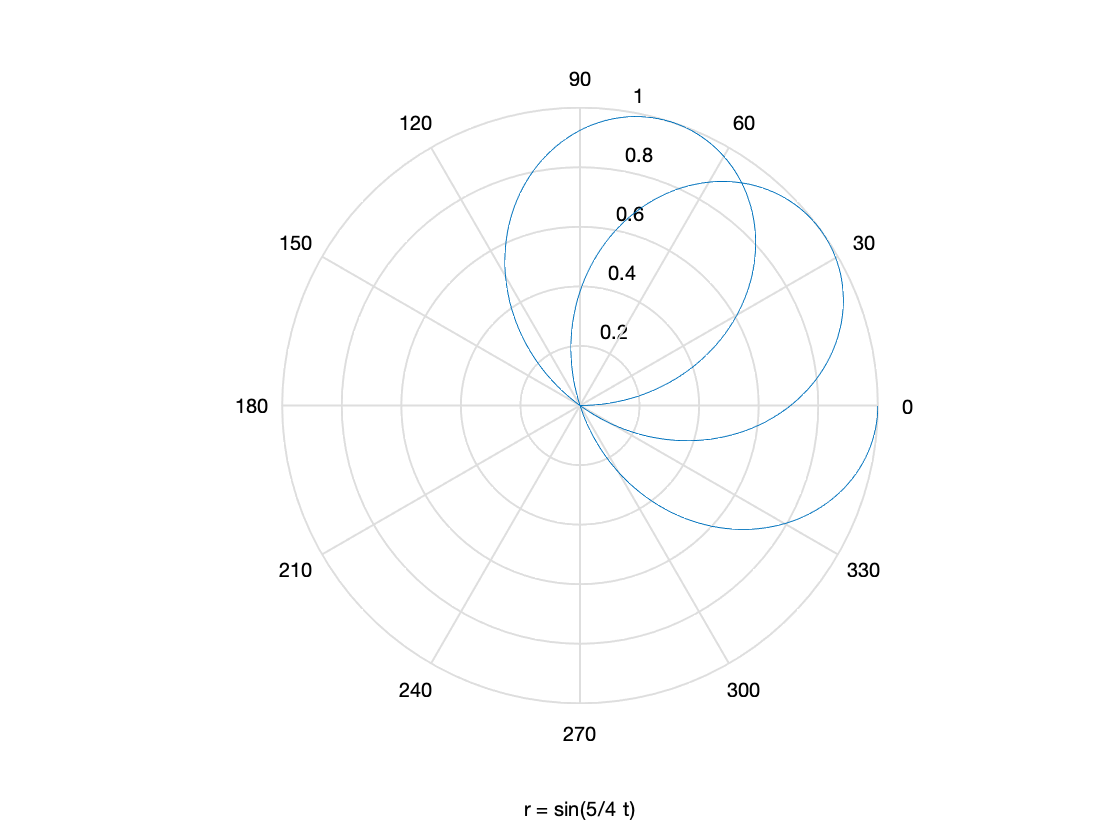

ezpolar(f);

## Customization

### Rotate Polar Axis

If it is desired for the theta axis to increase in the clockwise direction, set the *xdir* property of the current axis to *reverse. *To get 0 degrees to point upwards, rotate the theta-axis using the view function.

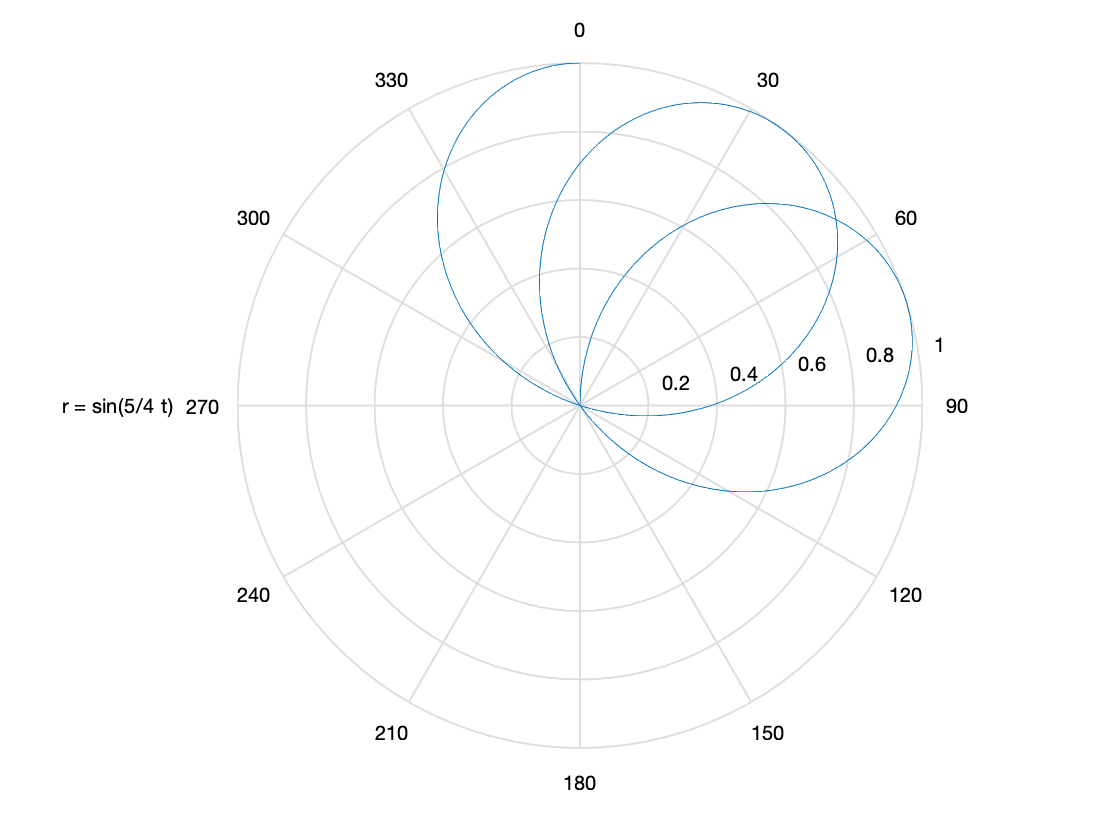

figure
e = ezpolar(f);
thetaRotation =90;

set(gca,"xdir","reverse")
view(thetaRotation,90);     % Specify the degree of rotation for the theta axis

### Specify Function Limits and Label Text

Use the 2nd input to `ezpolar` to specify the limits for which the function should be plotted. Change the font size of the automatic function label by modifying the Text object *FontSize* property. Use dot notation to access the Text object in the Children property of the Axes.

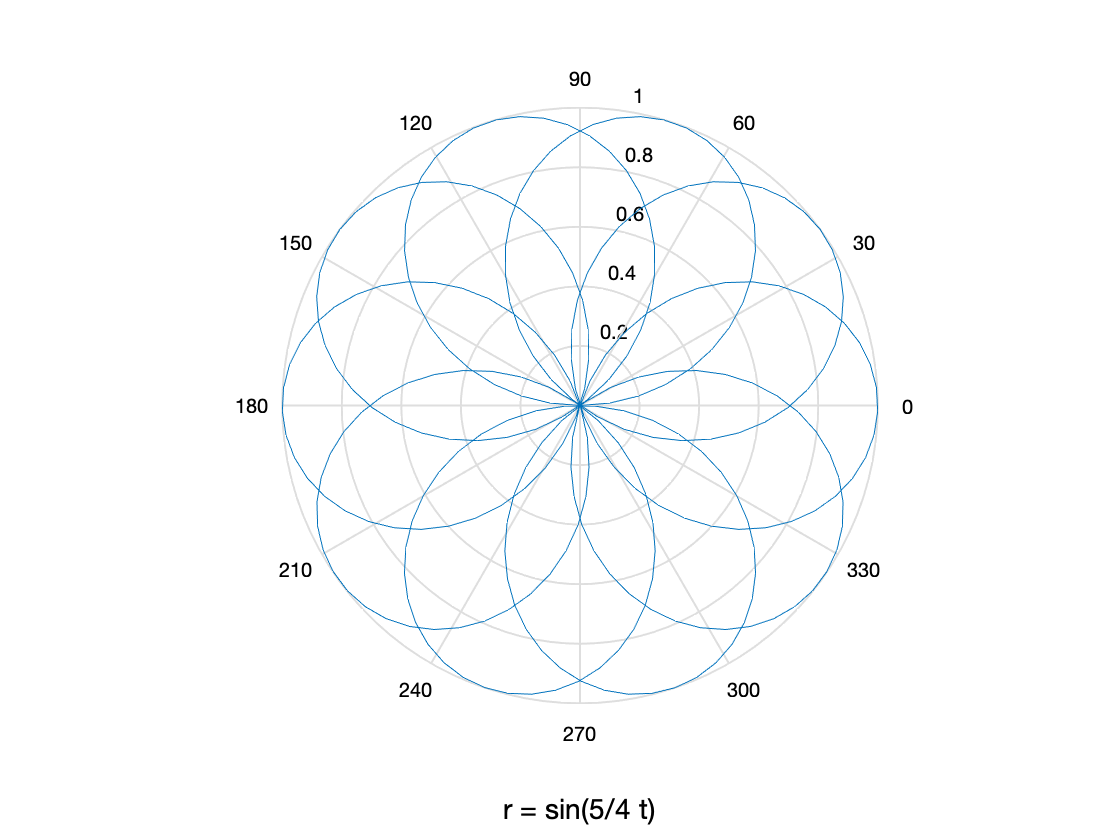

figure
e1 = ezpolar(f,[0, 8*pi]);                   % Specify function limits

ax = gca;                     
textObj = ax.Children(1);                    % Access Text object through Axes' Children property
textObj.FontSize =14;   % Specify FontSize of the Text object

### Specify Line Color and Width

Use dot notation to access the *LineWidth *and *Color *Properties of the Line Object generated from a call to `ezpolar`.

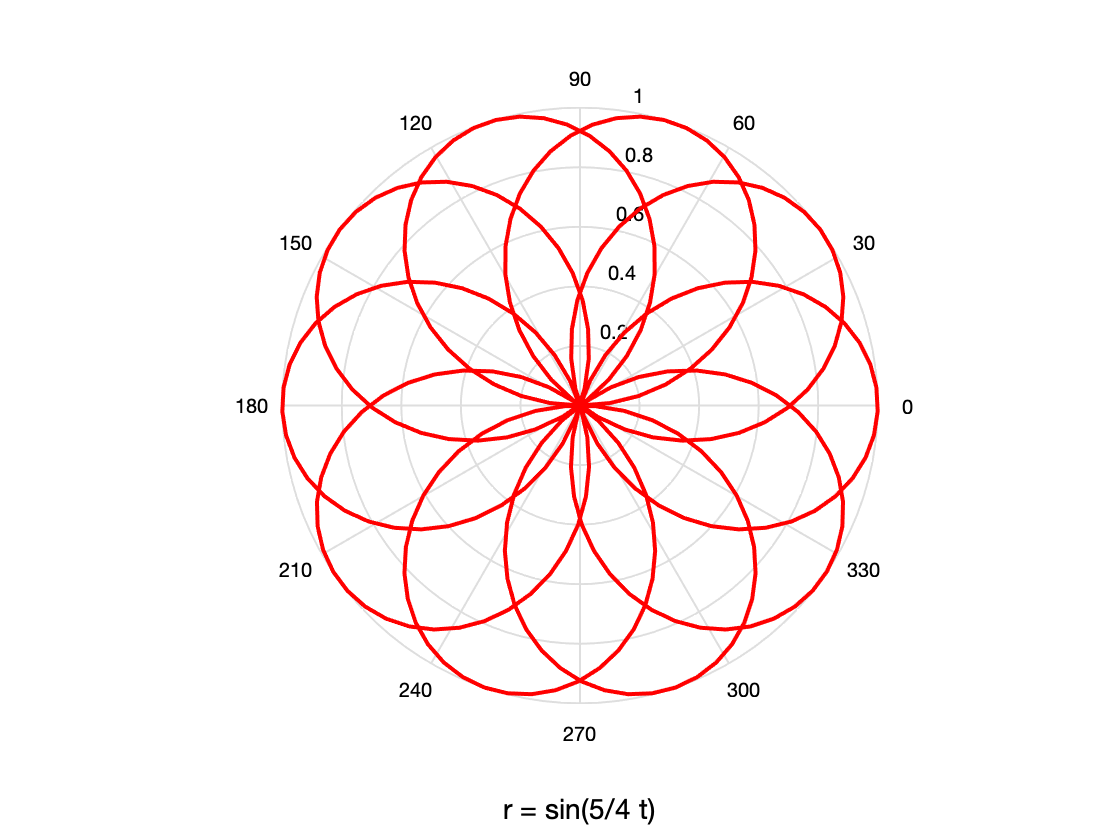

e2 = ezpolar(f,[0,8*pi]);

e2.LineWidth =2; % Specify LineWidth for each arrow
e2.Color = 'r';          % Specify Color for each arrow

ax = gca;
ax.Children(1).FontSize = 14;           % Specify function label font size

## **Additional Information**

### **Get All Line Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a Line Object, uncomment the following line of code.

% get(e)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[ezpolar](https://www.mathworks.com/help/matlab/ref/ezpolar.html)

Copyright (c) 2021, The MathWorks, Inc.